# GLAM Out-Of-Sample (OOS) Simulations

## House Keeping

### Load Data

The mat file loaded in below contains 3 tables: 

- oddTrials: data from odd-numbered trials--broken up by session

- simTrials: data from out of sample simulations--broken up by session 

- gof: table containing both simmulated and odd trials for the OOS procedures run separately for each monkey (not session-wise)

clear;close all;clc
rng(13,'twister') % random seed for replicability
load GLAM_OOS_ModelFit.mat

### Variable Definitions

The following variables appear in all tables:

- correctProb: value-corrected probability of choosing left

- rt: reaction time

- choice: which target was chosen (left = 1, right = 0)

The following variables appear in the *oddTrials *and *simTrials *tables:

- subject: session iondicator

- trial: this notes the specifc trial number. Notice that in the simTrials table, each trial is repeated 10 times

- leftValue: value of the left target

- rightValue: value of the right target

- leftGaze: proportion of time spent looking at the left target

- rightGaze: proportion of time spent looking at the right target

- gazeBins: bin for each trial based on the difference in left and right target gaze times 

- vDiff: left value - right value

- diffic: difficulty (|vDiff|)

- gazeDiff: proportion of time looking at the left target - proportion of time looking at the right target

- monk: monkey indicator (0 = Monkey C, 1 = Monkey K)

The *simTrials* table contains a variable called *repeat* and it indicates the number of the simulation (out of 10) for a trial 

The *gof *table  contains a variable called *isSim *which indicates whethere the data were from simulated or odd trials. 

## Assess Goodness of Fit

To determine goodness of fit, choice, rt, and value-corrected probability were regressed against a variable indicating if the data came from observed or simulated trials.  

choice_fit = fitglme(gof,'choice ~ isSim  + (isSim|monkey)','Distribution','Binomial');
anova_choice = anova(choice_fit)

anova_choice =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat      DF1    DF2           pValue    
    {'(Intercept)'}         25.073    1      1.6692e+05    5.5263e-07
    {'isSim'      }        0.65622    1      1.6692e+05        0.4179


rt_fit = fitglme(gof,'rt ~ isSim+(isSim|monkey)');
anova_rt = anova(rt_fit)

anova_rt =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat         DF1    DF2           pValue  
    {'(Intercept)'}        2.1345e+05    1      1.6692e+05           0
    {'isSim'      }            2.7302    1      1.6692e+05    0.098467


timeAdv = fitglme(gof,'correctProb ~ isSim + (isSim|monkey)');
anova_gaze = anova(timeAdv)

anova_gaze =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat         DF1    DF2           pValue
    {'(Intercept)'}        2.1115e-28    1      1.6692e+05    1     
    {'isSim'      }        6.8032e-28    1      1.6692e+05    1     


## Visualize Results

### Compute Sessionwise Metrics

% choice
choice_odd1 = grpstats(oddTrials,{'subject','vDiff','monk'},{'mean'},...
'DataVars','choice');
choice_odd = grpstats(choice_odd1,{'vDiff','monk'},{'mean','sem'},...
'DataVars','mean_choice');

choice_sim1 = grpstats(simTrials,{'subject','vDiff','monk'},{'mean'},...
    'DataVars','choice');
choice_sim = grpstats(choice_sim1,{'vDiff','monk'},{'mean','sem'},...
'DataVars','mean_choice');

% rt
rt_odd1 = grpstats(oddTrials,{'subject','diffic','monk'},{'mean'},...
'DataVars','rt');
rt_odd = grpstats(rt_odd1,{'diffic','monk'},{'mean','sem'},...
'DataVars','mean_rt');

rt_sim1 = grpstats(simTrials,{'subject','diffic','monk'},{'mean'},...
'DataVars','rt');
rt_sim = grpstats(rt_sim1,{'diffic','monk'},{'mean','sem'},...
'DataVars','mean_rt');

% corrected time advantage
timeAdvC_odd1 = grpstats(oddTrials,{'subject','gazeBins','monk'},{'mean'},...
'DataVars','correctProb');
timeAdvC_odd = grpstats(timeAdvC_odd1,{'gazeBins','monk'},{'mean','sem'},...
'DataVars','mean_correctProb');

timeAdvC_sim1 = grpstats(simTrials,{'subject','gazeBins','monk'},{'mean'},...
'DataVars','correctProb');
timeAdvC_sim = grpstats(timeAdvC_sim1,{'gazeBins','monk'},{'mean','sem'},...
'DataVars','mean_correctProb');


### Plot the Fits

White bars are the observed (odd-numbered) trials and the blue dots and lines show the simulated trials. Errorbars show session-wise standard error of the mean (SEM)

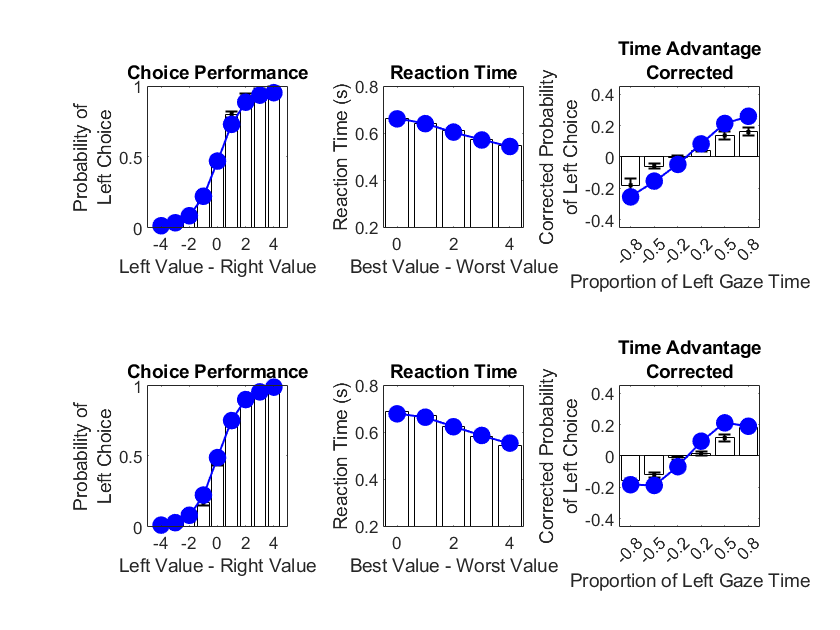

% find bin centers to label the x-axis of the third column
centers = [edges(1:end-1)+ diff(edges)/2; edges(end)+ diff(edges(1:2))/2];

clf
for monk = 1:2
    mm = [0 1];
    subplot(2,3,monk*3-2)
    bar(unique(oddTrials.vDiff),choice_odd.mean_mean_choice(choice_odd.monk == mm(monk)),'edgeColor','k','faceColor','none'); hold on
    errorbar(unique(oddTrials.vDiff),choice_odd.mean_mean_choice(choice_odd.monk == mm(monk)), ...
        choice_odd.sem_mean_choice(choice_odd.monk == mm(monk)),'k.', 'LineWidth',1); 
    errorbar(unique(simTrials.vDiff),choice_sim.mean_mean_choice(choice_sim.monk == mm(monk)), ...
        choice_sim.sem_mean_choice(choice_sim.monk == mm(monk)),'b.-', 'MarkerSize', 30,'LineWidth',1);
    xlabel('Left Value - Right Value')
    ylabel({'Probability of', 'Left Choice'})
    xticks([-4 -2 0 2 4])
    xticklabels([-4 -2 0 2 4])
    yticks([0,0.5,1])
    ylim([0 1])
    title('Choice Performance')
    pbaspect([1 1 1])

    subplot(2,3,monk*3-1)
     bar(unique(oddTrials.diffic),rt_odd.mean_mean_rt(rt_odd.monk == mm(monk)),'edgeColor','k','faceColor','none'); hold on
    errorbar(unique(oddTrials.diffic),rt_odd.mean_mean_rt(rt_odd.monk == mm(monk)), ...
        rt_odd.sem_mean_rt(rt_odd.monk == mm(monk)),'k.', 'LineWidth',1); 
    errorbar(unique(simTrials.diffic),rt_sim.mean_mean_rt(rt_sim.monk == mm(monk)), ...
       rt_sim.sem_mean_rt(rt_sim.monk == mm(monk)),'b.-', 'MarkerSize', 30,'LineWidth',1);
    xlim([-0.5,4.5])
    ylim([0.200,0.800])
    yticks([0.2:0.20:0.8])
   % yticklabels([200:200:800])
    xticks([0 2 4])
    xticklabels([0 2 4])
    xlabel('Best Value - Worst Value')
    ylabel('Reaction Time (s)')
    pbaspect([1 1 1])
    title('Reaction Time')
    subplot(2,3,monk*3)
    
    
    bar(centers,timeAdvC_odd.mean_mean_correctProb(timeAdvC_odd.monk == mm(monk)),'edgeColor','k','faceColor','none'); hold on
    errorbar(centers,timeAdvC_odd.mean_mean_correctProb(timeAdvC_odd.monk == mm(monk)), ...
        timeAdvC_odd.sem_mean_correctProb(timeAdvC_odd.monk == mm(monk)),'k.', 'LineWidth',1);
    errorbar(centers,timeAdvC_sim.mean_mean_correctProb(timeAdvC_sim.monk == mm(monk)), ...
        timeAdvC_sim.sem_mean_correctProb(timeAdvC_sim.monk == mm(monk)),'b.-', 'MarkerSize', 30,'LineWidth',1);

    title({'Time Advantage','Corrected'})
    xlabel('Proportion of Left Gaze Time')
    ylabel({'Corrected Probability', 'of Left Choice'})
    ylim([-0.45 0.45])
    yticks([-0.4:0.2:0.4])

    xticks(centers)
    xticklabels(round(centers,1,'sig'))
    xtickangle(45)
    pbaspect([1 1 1])
end